% Leggo file 
info_validation = readtable("../visual_proj/val_info.csv"); 

%% Leggo le immagini 
validation = [];
validation_degr = [];
for i=1:size(info_validation,1)
        
        if mod(i, 200) == 0
            disp(['Immagine considerata ', num2str(i), ' di ', num2str(size(info_validation,1))]);
        end

        im1=imread(strcat("../visual_proj/val_set/", info_validation{i,1}));
        im2=imread(strcat("../visual_proj/val_set_degraded/", info_validation{i,1}));
        validation=[validation brisque(im1)];
        validation_degr=[validation_degr brisque(im2)];
end

Immagine considerata 200 di 11994
Immagine considerata 400 di 11994
Immagine considerata 600 di 11994
Immagine considerata 800 di 11994
Immagine considerata 1000 di 11994
Immagine considerata 1200 di 11994
Immagine considerata 1400 di 11994
Immagine considerata 1600 di 11994
Immagine considerata 1800 di 11994
Immagine considerata 2000 di 11994
Immagine considerata 2200 di 11994
Immagine considerata 2400 di 11994
Immagine considerata 2600 di 11994
Immagine considerata 2800 di 11994
Immagine considerata 3000 di 11994
Immagine considerata 3200 di 11994
Immagine considerata 3400 di 11994
Immagine considerata 3600 di 11994
Immagine considerata 3800 di 11994
Immagine considerata 4000 di 11994
Immagine considerata 4200 di 11994
Immagine considerata 4400 di 11994
Immagine considerata 4600 di 11994
Immagine considerata 4800 di 11994
Immagine considerata 5000 di 11994
Immagine considerata 5200 di 11994
Immagine considerata 5400 di 11994
Immagine considerata 5600 di 11994
Immagine considerata 580

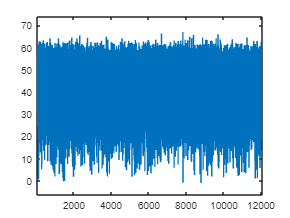


%% Plot 
media_brisque_validation = mean(validation); %28.8337
media_brisque_validation_degr = mean(validation_degr);  %40.0605
figure(2), plot(validation_degr)

Calcolo % immagini degradate in val set degradato

% Inizializza il contatore per le immagini con valore BRISQUE superiore alla media
num_immagini_sopra_media = 0;

% Itero attraverso il set di validazione degradato e controllo quante
% immagini hanno valore di BRISQUE maggiore della media
for i = 1:length(validation_degr)
    if validation_degr(i) > media_brisque_validation_degr
        num_immagini_sopra_media = num_immagini_sopra_media + 1;
    end
end

% Stampa il risultato
disp(['Numero di immagini nel set di validazione degradato con valore BRISQUE superiore alla media: ', num2str(num_immagini_sopra_media)]);

Numero di immagini nel set di validazione degradato con valore BRISQUE superiore alla media: 6239
